%%Lab 1 section c

% Calculate the structural errors throughout the given range of input angles and
%           at an increment of 5
% for the two cases in (a) and (b). 
%Plot the variation of the
%   structural errors as a function of the input angles for the two cases 
%       and in the same axis

%%
%Structural errors for a.
%Values of K1, K2 and K3
theta2 = chebyshev(15,165,3)

theta2 =   154.9519
   90.0000
   25.0481


theta4 = rel (theta2)

theta4 =   131.6293
  103.7000
   75.7707


%Values for K1, K2, K3 are found in the vector K
K = freudenstein(theta2, theta4)

K =    -7.1003
   -3.4091
   -0.7101


k1 = K(1,1)

k1 = -7.1003

k2 = K(2,1)

k2 = -3.4091

k3 = K(3,1)

k3 = -0.7101

inpRange = (15: 5: 165)'

inpRange =     15
    20
    25
    30
    35
    40
    45
    50
    55
    60


outRange = rel(inpRange)

outRange =    71.4500
   73.6000
   75.7500
   77.9000
   80.0500
   82.2000
   84.3500
   86.5000
   88.6500
   90.8000


%%Computing the structural error
e = k1*(cosd(outRange)) - k2*(cosd(inpRange)) + k3 - cosd(inpRange - outRange)

e =    -0.2287
   -0.1048
   -0.0009
    0.0835
    0.1491
    0.1970
    0.2282
    0.2439
    0.2456
    0.2346


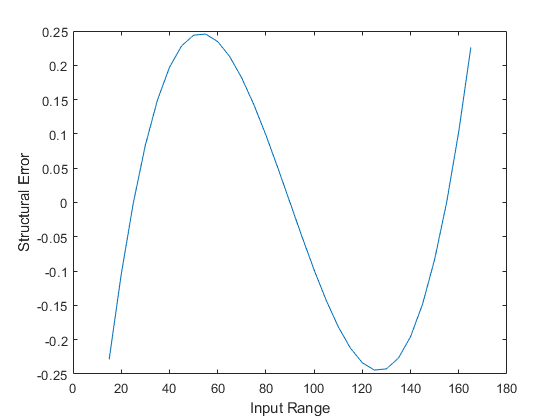

plot (inpRange, e)
xlabel("Input Range")
ylabel("Structural Error")

%%Computing the structural error for b